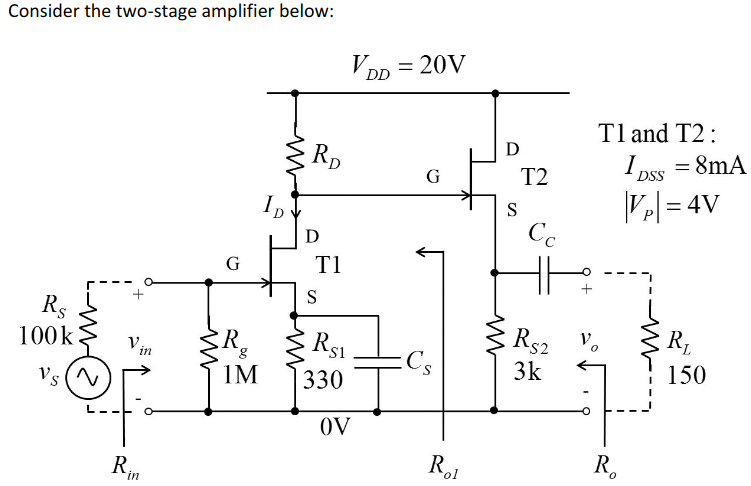

syms I_D I_DSS V_GS V_P V_G V_S R_S1 I_S V_DD

constants = [
    V_P == -4
    I_DSS == 8e-3
    V_DD == 20
]

$$constants = \left(\begin{array}{c} V_{P}=-4\\ I_{\mathrm{DSS}}=\frac{1}{125}\\ V_{\mathrm{DD}}=20 \end{array}\right)$$


fet_eqn = I_D == I_DSS * (1 + V_GS / abs(V_G))^2

$$fet\_eqn = I_{D}=I_{\mathrm{DSS}}\,{\left(\frac{V_{\mathrm{GS}}}{\left|V_{G}\right|}+1\right)}^{2}$$

gate_voltage = V_GS == V_G - V_S

$$gate\_voltage = V_{\mathrm{GS}}=V_{G}-V_{S}$$

axioms = [
    V_S == I_S * R_S1
    V_G == 0
    I_S == I_D
]

$$axioms = \left(\begin{array}{c} V_{S}=I_{S}\,R_{\mathrm{S1}}\\ V_{G}=0\\ I_{S}=I_{D} \end{array}\right)$$


solve_for([I_D V_GS], [ ...
    constants
    
    fet_eqn
    gate_voltage
    axioms
])

 
ans =
 
Empty sym: 0-by-9
 


% I_D == 3.8e-3

g_m = 2.7e-3 % obtained graphically

g_m = 0.0027

syms R_S2 I_D2 V_O V_GS2 V_S2 V_G2 g_m2

t2_kvl = V_O == I_D2 * R_S2

$$t2\_kvl = V_{O}=I_{\mathrm{D2}}\,R_{\mathrm{S2}}$$

output_req = V_O == 9

$$output\_req = V_{O}=9$$


fet_eqn_t2 = I_D == I_DSS * (1 + V_GS2 / abs(V_G))^2

$$fet\_eqn\_t2 = I_{D}=I_{\mathrm{DSS}}\,{\left(\frac{V_{\mathrm{GS2}}}{\left|V_{G}\right|}+1\right)}^{2}$$

gate_t2 = V_G2 == V_S2 + V_GS2

$$gate\_t2 = V_{\mathrm{G2}}=V_{\mathrm{GS2}}+V_{\mathrm{S2}}$$

transconductance_t2 = g_m2 == 2 * I_DSS / abs(V_P) * (1 + V_GS2 / abs(V_G))

$$transconductance\_t2 = g_{\mathrm{m2}}=\frac{2\,I_{\mathrm{DSS}}\,\left(\frac{V_{\mathrm{GS2}}}{\left|V_{G}\right|}+1\right)}{\left|V_{P}\right|}$$


% WRONG! TODO
solve_for(g_m2, [ ...
    constants
    
    t2_kvl
    output_req
    gate_t2
    transconductance_t2
])

$$ans = 0.004239$$

syms V_D1 R_D

shorted = V_D1 == V_G2

$$shorted = V_{\mathrm{D1}}=V_{\mathrm{G2}}$$

kvl_d1 = V_DD == V_D1 + R_D * I_D

$$kvl\_d1 = V_{\mathrm{DD}}=V_{\mathrm{D1}}+I_{D}\,R_{D}$$

syms v_gs v_o1 v_in A_v1
% see blue a4 book for diagram
ss_v_o1 = v_o1 == -g_m * v_gs * R_D

Unrecognized function or variable 'v_o1'.

ss_gain = A_v1 == v_o1 / v_in
% output_res = R_O1 == 

syms v_o2 v_gs2 R v_in2 A_v2 R_o2
syoutput2 = v_o2 == g_m2 * v_gs2 * R_S2
% input2 = v_in2 == v_gs + TODO
gain2 = A_v2 == v_o2 / v_in2
output_z2 = R_o2 == zpar([r_s R_S2])
r_s_definition = r_s == g_m2^-1

vdiv1 = v_in == vdiv(V_S, R_in, R_S1)
total_gain = v_div(v_div(A_v1, R_S1, R_in), R_O, R_L)